close all;
addpath(genpath('~/Documents'));
addpath(genpath('/calculSSD/salome'));

simuDirAll = '/calculSSD/salome/Simulation-28mars';
simuNameW = '/Bone227G-Image1590-F0.06/';
simuNameR = '/Bone227G-Image1590-F1.25/';
filename = '~/Documents/BoneRugosity/RMS/BoneSample/227G/SAMPLE_227G_SLICE_1590.bmp';
segmented = false;
boundaryEndost = ExtractBoundary(filename, segmented); boundaryEndost(2, :) = max(boundaryEndost(2, :)) - boundaryEndost(2, :);
% Compute necessary information, for mor details, check ProfileSpectrum.mlx
delta_x = 9e-3; Fs = 1/delta_x; L = size(boundaryEndost, 2); fc = 2.5/35;
profile = boundaryEndost(2, 2:end) * delta_x; x = (0:L-1)*1/Fs;
frequencies = logspace(log10(1e-3), log10(50), 50); 
meanH = zeros(1, length(frequencies));
for i = 1 : length(frequencies)
    [profile, roughness, xProfile] = GetRoughness(filename, frequencies(i), false);
    meanH(1, i) = mean(roughness);
end
frequencies = frequencies/(10*fc);

% Post-Process
[~, ProbaW, AngleW, reconstructionW] = PostProcessing([simuDirAll, simuNameW]);

----------Getting 1D specular transform----------
Elapsed time is 41.649019 seconds.
---------GET SPECULAR TRANSFORM MODELS---------
	Soft Tissues
Elapsed time is 4.064060 seconds.
Elapsed time is 0.586109 seconds.


[~, ProbaR, AngleR, reconstructionR] = PostProcessing([simuDirAll, simuNameR]);

----------Getting 1D specular transform----------
Elapsed time is 45.616744 seconds.
---------GET SPECULAR TRANSFORM MODELS---------
	Soft Tissues
Elapsed time is 4.031743 seconds.
Elapsed time is 0.535228 seconds.


parametersR = load(fullfile(simuDirAll, simuNameR, 'parameters.mat'));
parametersW = load(fullfile(simuDirAll, simuNameW, 'parameters.mat'));

# Results of the ex-vivo parametrics study

The objective of this study is to establish quantifiable parameters for assessing the roughness of bone endostium. Existing literature suggests that surface roughness can be effectively quantified by evaluating the **root mean square of height** relative to a planar surface, along with the **correlation length of height**, which provides insights into the horizontal dimension of surface irregularities. However, these parameters have not been characterized within the context of bone.

Consequently, our initial step involves conducting an analysis of bone imagery acquired via X-ray to discern and define these parameters specific to bone morphology.

## Introduction to the notion of waviness

The concepts such as waviness, roughness, and form are central in the study of a surface roughness. By examining the spatial frequency spectrum of a profile, we can discern the distinct  contributions of various components characterized by different frequencies, as illustrated in the following figure.

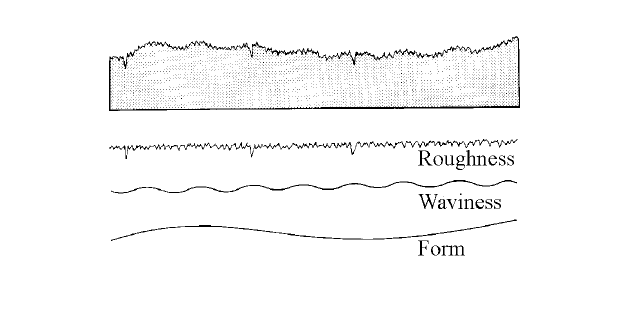

imageData = imread('The-measured-profile-is-the-addition-of-roughness-waviness-and-form.png');
imshow(imageData);

## Analysis of ex-vivo bones

The images where acquired on several ex-vivo bones with various profiles. The endost was extraxted using the `ExtractBoundary.m` function on a binarize image. The resolution of the X-Ray image is $9\mu m$.  

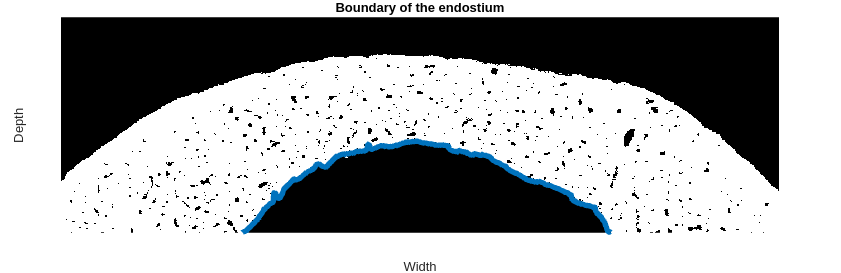

openfig('BoundaryEndost.fig');

### Cut off frequency determination 

In order to extract the rougness and both the waviness and the roughness components of the profile, we need to determine the cutt off frequency of the highpass filter. The usual cut off frequency to obtain *only the roughness* is a frequency that corresponds to a pattern of $0\ldotp 8\textrm{mm}$ thus a frequency $k_{\textrm{industry}} =1\ldotp 25\;\textrm{mm⁻¹}$, in the industry. 

In order to obtain the corresponding values for the bone. We computed the mean height of the profile for various cut off frequency. When the mean heigth is equal to zero, we can consider that the parabolic form of the bone as been filtred, we therefore have the *roughness and the waviness* components. 

In order to give significance to our reults, we ploted the mean heigth regarding the frequency that corresponds to the wavelength in the bone, considering a velocity of $c=3500m\ldotp \textrm{s⁻¹}$ and a temporale frequency $f_{\textrm{acq}} =2,5\textrm{Mhz}$: 


$$k_{\lambda } =\frac{1}{\lambda }=\frac{1}{c/f_{\textrm{acq}} }\approx 0\ldotp 741\;\textrm{mm⁻¹}$$


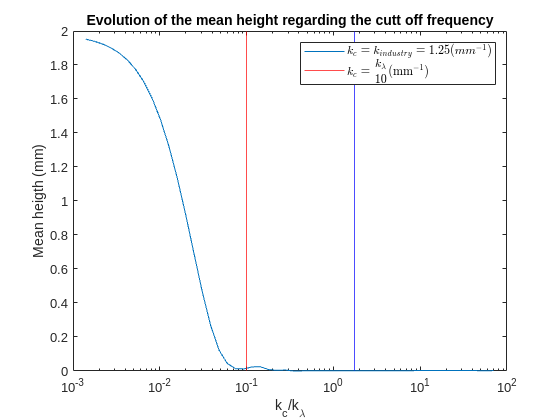

figure
semilogx(frequencies, meanH);
hold on 
xline(1/10, 'r');
xline(1.25/(10*fc), 'b');
hold off
title('Evolution of the mean height regarding the cutt off frequency');
ylabel('Mean heigth (mm)');
xlabel('k{_c}/k{_\lambda}');
legend('$k_c = k_{industry} = 1.25 (mm^{-1})$', '$$k_c = \frac{k_{\lambda}}{10} \mathrm{(mm^{-1})}$$', 'Interpreter', 'latex');

The results allow us to see that the frequency that allow to extract the waviness *and* the roughness, which corresponds to the blue line, is $\frac{k_{\lambda } }{10}\approx 0\ldotp 0741\;\textrm{mm⁻¹}$. The frequency that allow to extract only the roughness, according the the industry is plotted in blue. 

We will know refer to the combination of roughness and waviness as waviness.

### Root mean square of the extracted profile

The profile was filtred using the `highpass` function with the frequencies of interest. 

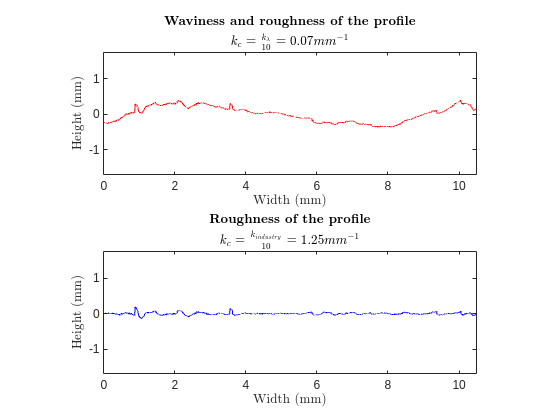

figure
subplot(2,1,1)
plot(x, highpass(profile, 0.07, Fs), 'r');
title('\bf Waviness and roughness of the profile', '$k_c = \frac{k_{\lambda}}{10} = 0.07 mm^{-1}$', 'Interpreter', 'latex');
xlabel('Width (mm)', 'Interpreter', 'latex');
ylabel('Height (mm)', 'Interpreter', 'latex');
axis equal
subplot(2,1,2)
plot(x, highpass(profile, 1.25, Fs), 'b');
title('\bf Roughness of the profile', '$k_c = \frac{k_{industry}}{10} = 1.25 mm^{-1}$', 'Interpreter', 'latex');
xlabel('Width (mm)', 'Interpreter', 'latex');
ylabel('Height (mm)', 'Interpreter', 'latex');
axis equal

CorrW = ComputeCorr(highpass(profile, 0.07, Fs), recorded.Spatial_step_mm);
CorrR = ComputeCorr(highpass(profile, 1.25, Fs), recorded.Spatial_step_mm);

We can clearely distinguish from the original profile, the waviness and the roughness. The root mean square of these extracted profiles have distinct root mean square value. The profile as a RMS of ${\textrm{RMS}}_{\textrm{waviness}} \approx 214\mu m$and ${\textrm{RMS}}_{\textrm{roughness}} \approx 33\mu m$ and a correlation length of $\rho_{\textrm{waviness}} =7,52\textrm{mm}$ and $\rho_{\textrm{waviness}} =0,08\textrm{mm}$. 

### Validation on other bones

These values have been validated on other image of the same bone and on other bones.

## Simulation on waviness and roughness of ex-vivo bones

In order to observe the interaction of the ultrasounds regarding the two type of extracted profile. We did a `SimSonic` simulation with the bone/soft tissu interface being both the roughness and waviness profiles. The original curved profile measured $15\textrm{mm}$. We therefore did a extention of the waviness and roughness to recover the original length of the endosteium and a symmetry in order to reach a geometry of $30\textrm{mm}$ of width. 

The map generated allog side with the specularity map obtained are depicted in the following figure. 

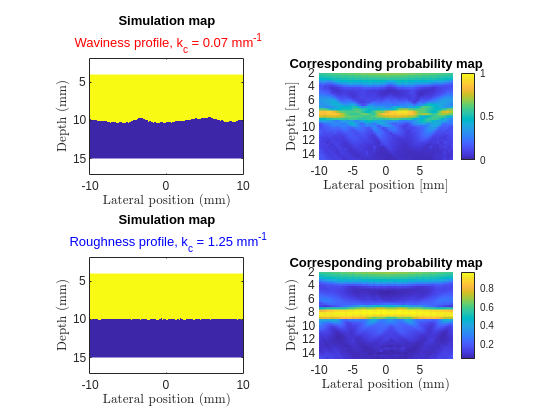

figure
subplot(2,2,1)
[Map,~,~] = SimSonic2DReadMap2D([simuDirAll, simuNameW, 'Geometry.map2D']);
X = 5:0.01:25-0.01; X = X -mean(X);
Z = flipud(4:0.01:15-0.01);
imagesc(X, Z, Map(400:end-1, 500:2499))
axis equal
xlabel('Lateral position  (mm)', Interpreter='latex');
ylabel('Depth (mm)', Interpreter='latex');
title('Simulation map', '\color{red} Waviness profile, k_c = 0.07 mm^{-1}');
subplot(2,2,3)
[Map,~,~] = SimSonic2DReadMap2D([simuDirAll, simuNameR, 'Geometry.map2D']);
X = 5:0.01:25-0.01; X = X -mean(X);
Z = flipud(4:0.01:15-0.01);
imagesc(X, Z, Map(400:end-1, 500:2499))
axis equal
xlabel('Lateral position  (mm)', Interpreter='latex');
ylabel('Depth (mm)', Interpreter='latex');
title('Simulation map', '\color{blue} Roughness profile, k_c = 1.25 mm^{-1}');
subplot(2,2,2)
Xinit = 500;
Zinit = 600;
pcolor(reconstructionW.Xmm,reconstructionW.Zmm,ProbaW)
xlabel('Lateral position [mm]', Interpreter='latex')
ylabel('Depth [mm]', Interpreter='latex')
colorbar
title('Corresponding probability map')
axis ij image, shading flat
clim([0 1])
subplot(2,2,4)
pcolor(reconstructionR.Xmm, reconstructionR.Zmm, ProbaR) 
axis tight
title('Corresponding probability map')  
shading flat
xlabel('Lateral position (mm)', Interpreter='latex')
ylabel('Depth (mm)', Interpreter='latex')
axis ij image;
colorbar

The specularity map indicates the probability that the surface at the corresponding pixel is part of a specular interface or rather a diffuse interface. 

### Metrics to quantify the rugosity

In order to quantify the differencies between the roughness and the waviness, we selected a region of interest (ROI) of one wavelength in the bone, so $\lambda =1\ldotp 4\textrm{mm}$. 

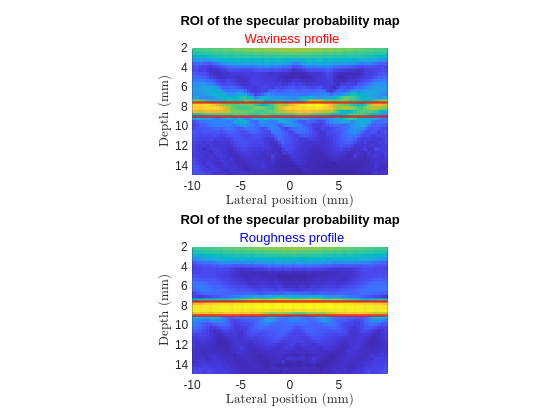

[ROI_R, LimInfR, LimSupR] = ExtractROI(ProbaR, parametersR, reconstructionR);
[ROI_W, LimInfW, LimSupW] = ExtractROI(ProbaW, parametersW, reconstructionW);
figure
subplot(2,1,1)
pcolor(reconstructionR.Xmm, reconstructionR.Zmm, ProbaW) 
yline(reconstructionR.Zmm(LimInfR), 'Color', 'red', 'LineWidth', 2);
yline(reconstructionR.Zmm(LimSupR) , 'Color', 'red', 'LineWidth', 2);
shading flat
xlabel('Lateral position (mm)', Interpreter='latex')
ylabel('Depth (mm)', Interpreter='latex')
title('ROI of the specular probability map', '\color{red} Waviness profile') 
axis ij image;
subplot(2,1,2)
pcolor(reconstructionR.Xmm, reconstructionR.Zmm, ProbaR) 
yline(reconstructionR.Zmm(LimInfR), 'Color', 'red', 'LineWidth', 2);
yline(reconstructionR.Zmm(LimSupR) , 'Color', 'red', 'LineWidth', 2);
shading flat
xlabel('Lateral position (mm)', Interpreter='latex')
ylabel('Depth (mm)', Interpreter='latex')
title('ROI of the specular probability map', '\color{blue} Roughness profile') 
axis ij image;

We then calculate the mean for each lateral position. The results reveal that the probability of specularity is higher for the roughness profile, which is coherent since we are unable to distinguish the small asperities of the roughness due to the low ultrasound resolution. The probability of the waviness profile along the lateral position is not constant. There are drops in the probabilities around values of 0.5 at locations where we have larger holes or peaks.

To further describe the profile, we utilize two values: the mean and the standard deviation. The values presented in the following table demonstrate that we can adequately describe the profile using these two parameters in this case. 

# Parametric study of the root-mean-square and correlation length of a height profile

pathSimuAll = '/calculSSD/salome/Simulation-04avr';
rmsAll = 0.03 + (0:9) * 0.05;      % List of rms values (mm)
corrAll = [0.5 1 2 4];             % List of correlation length (mm)

load('SpecularAll.mat')

We identified two parameters that allow us to describe the type of endosteum profile: roughness and waviness profiles, which are linked to correlation length and root-mean-square (RMS) parameters. To validate whether the output parameters accurately describe the profile, we conducted 40 simulations across 10 different values of RMS and correlation length.

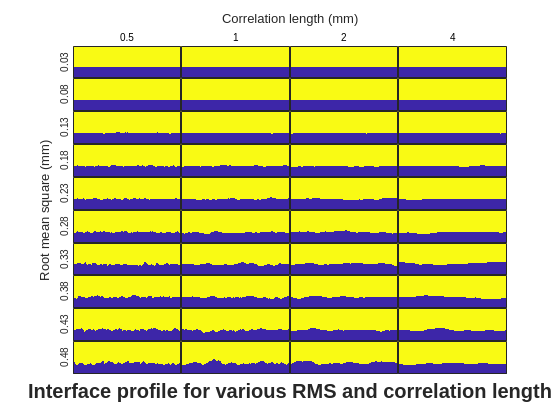

MapTitle = 'Interface profile for various RMS and correlation length';
PlotMap(SpecularAll.Map, rmsAll, corrAll, MapTitle);

We then compute the specular probability map. The yellow color correspond to a probability of 1. Therefore the probability that pixel at this position is part of a specular plan. And the blue color corresponds to a probability of specularity equal to 0. Which indicates that the pixel is a diffuse point. 

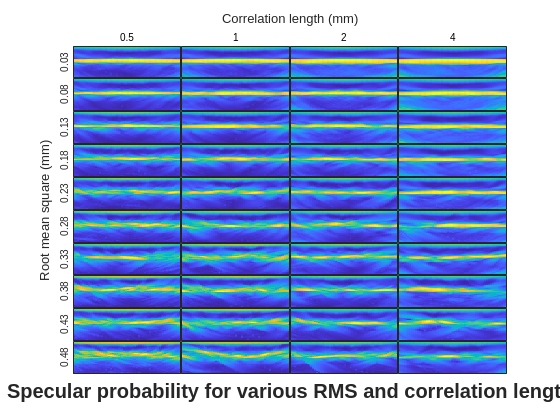

MapTitle = 'Specular probability for various RMS and correlation length';
PlotMap(SpecularAll.SpecuMap, rmsAll, corrAll, MapTitle);

In order to quantify the specularity of the interface, we extract a Region Of Interest (ROI) with a width equivalent to one wavelength around the presumed interface, as illustrated in the following figure. Subsequently, we calculate the mean probability at each lateral position to observe the average linear probability. The results reveal a tendency of probability decrease with increasing correlation length and decreasing root-mean-square (RMS) values.

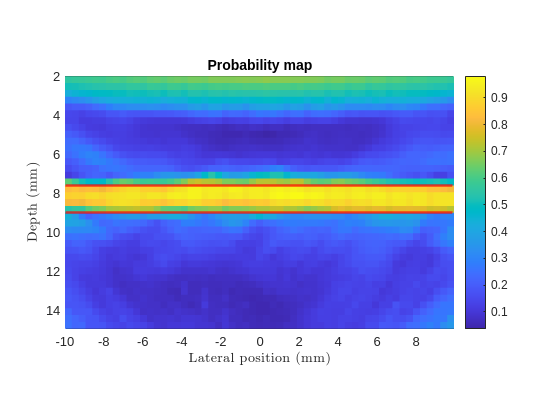

ProbaROI(SpecularAll.SpecuMap{1,1}{1}, reconstruction, parametersR, true);

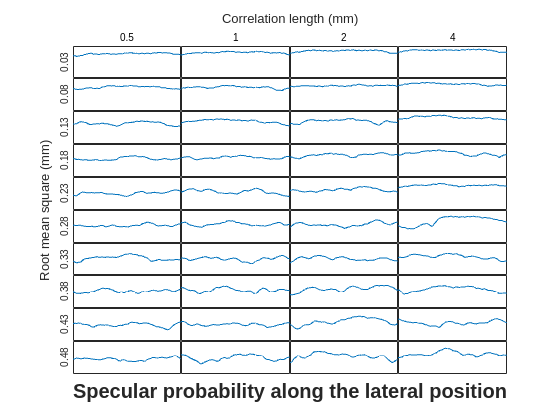

MapTitle = 'Specular probability along the lateral position';
PlotAll('SpecuProba', SpecularAll, rmsAll, corrAll, pathSimuAll, MapTitle);

Next, we compute the mean ROI over the entire zone of interest, thereby obtaining a value that describes the specularity of the interface. 

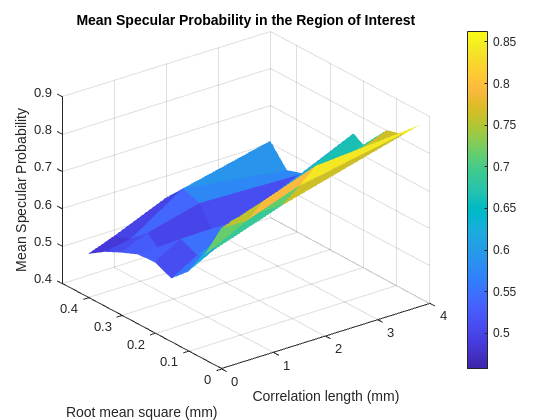

figure;
surf(corrAll, rmsAll, table2array(meanROI), 'EdgeColor', 'none');
xlabel('Correlation length (mm)');
ylabel('Root mean square (mm)');
zlabel('Mean Specular Probability');
title('Mean Specular Probability in the Region of Interest');
colorbar

The ploted surface allows us to estimate that we have a linear relation between the mean in the ROI and the initial inputs parameters, the RMS and the correlation length. Therefore, we can apply a regressive linear model in order to obtain the relationship. 

The results of this regression model is the following : 

disp(mdl);

Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                        Estimate                 SE                  tStat                 pValue       
                   __________________    ___________________    ________________    ____________________

    (Intercept)     0.719046581145464     0.0170289439208497    42.2249661803799    6.60353190261707e-33
    x1             0.0346578509253306    0.00513966565776983    6.74321118007686    6.24747501263437e-08
    x2             -0.637819350091345     0.0479729939295927    -13.295383461525    1.15264091168089e-15


Number of observations: 40, Error degrees of freedom: 37
Root Mean Squared Error: 0.0436
R-squared: 0.857,  Adjusted R-Squared: 0.85
F-statistic vs. constant model: 111, p-value = 2.28e-16


This means that wwe have the following relationship : 


$$\bar{s} =0\ldotp 035\rho -0\ldotp 638\sigma +0\ldotp 719,\textrm{with}\;\bar{s} \;\textrm{the}\;\textrm{mean}\;\textrm{specularity},\rho \;\textrm{the}\;\textrm{correlation}\;\textrm{length}\;\textrm{and}\;\sigma \;\textrm{the}\;\textrm{root}\;\textrm{mean}\;\textrm{square}\ldotp \;$$


The p values as well as the $R^2$ value indicate that the results are plausible and can be taken in consideration. Even if there is variability in the generation of surfaces regarding the input parameters. 

T = table([0.05; 0.001], [0.2143; 0.0086], [12.938; 1.2488], ...
    'VariableNames', {'RMS', 'Correlation length', 'Rugosity'}, ...
    'RowNames', {'mean' , 'std'});

The resolution of the ultrasound imaging algorithme is 

function[ROI, LimInf, LimSup] = ExtractROI(SpecularProbaMap, parameters, reconstruction)
% This function allows to extract the zone of interest that coresponds to
% the bone/tissu interface in the specularity probability map.

    % Interface depth
    to_px = @(mm) round(mm*1e-3/reconstruction.pixel_size)+1;       % The values in reconstruction are expressed in meter
    specularDepth = 1.7;                                              % The specularity Map starts at 2mm from the probe.
    specularInterface = parameters.interface.depth - parameters.probe.depth - specularDepth;
    
    % Length of the ROI
    lengthROI = 1*(parameters.medium.cp(2) / (parameters.probe.fc)*1e3);       % Number of wavelength in the bone that we consider (mm)
    LimInf = to_px(specularInterface - lengthROI/2);
    LimSup = to_px(specularInterface + lengthROI/2);
    ROI = SpecularProbaMap(LimInf : LimSup, :);
end

function[Table] = ComputeMap(MapType, rmsAll, corrAll, pathSimuAll, SpecularAll)
    % Compute parameters once 
    format = 'simulation_rms_%.2f_cl_%.1f/';
    simuDir1 = fullfile(pathSimuAll, sprintf(format, rmsAll(1), corrAll(1)));
    parameters = load(fullfile(simuDir1, 'parameters.mat'));
    recorded = LoadRfData(parameters.probe, simuDir1);
    [~, reconstruction] = GenerateParamRecon(recorded);

    Table = table('Size', [numel(rmsAll), numel(corrAll)], ...
                'VariableType', repmat({'cell'}, 1, numel(corrAll)), ...
                'VariableNames', cellstr(string(corrAll)), ...
                'RowNames', cellstr(string(rmsAll)));

    % Generate Map and probability regarding the case 
    for i = 1:numel(rmsAll)
        rms = str2double(Table.Properties.RowNames{i});
        for j = 1:numel(corrAll)
            corr = str2double(Table.Properties.VariableNames{j});
            simu_dir = fullfile(pathSimuAll, sprintf(format, rms, corr));
    
            % Compute the required type of simulation 
            switch MapType
                case 'Map'
                    [Map,~,~] = SimSonic2DReadMap2D([simu_dir, 'Geometry.map2D']);
                    Table{i,j}{1} = Map;
                   
                case 'SpecuMap'
                    if exist(fullfile(simu_dir, 'postProcess.mat'))
                        postProcess = load(fullfile(simu_dir, 'postProcess.mat'));
                        Table{i,j}{1} = postProcess.SpecularProbaMap;
                    end
                case 'SpecuProba'
                    try
                        probability = ProbaROI(SpecularAll.SpecuMap{i,j}{1}, reconstruction, parameters, false);
                        Table{i,j}{1} = probability;
                        disp(i)
                    end
                otherwise 
                    warning('Unexpected Map type. No data computed.')
            end
        end
    end
end

function[] = PlotAll(MapType, Struct, rmsAll, corrAll, pathSimuAll, MapTitle)
    Table = getfield(Struct, MapType);

    % Compute parameters once 
    format = 'simulation_rms_%.2f_cl_%.1f/';
    simuDir1 = fullfile(pathSimuAll, sprintf(format, rmsAll(1), corrAll(1)));
    parameters = load(fullfile(simuDir1, 'parameters.mat'));
    recorded = LoadRfData(parameters.probe, simuDir1);
    [~, reconstruction] = GenerateParamRecon(recorded);

    figure
    t = tiledlayout(numel(rmsAll),numel(corrAll),'TileSpacing','tight');
    % Plot Map
    for i = 1:numel(rmsAll)
        for j = 1:numel(corrAll)
            % Plot each map
            nexttile(t)
            switch MapType
                case {'Map', 'SpecuMap'}
                    try
                        img = Table{i,j}{1};
                        imagesc(img);
                    end
                case 'SpecuProba'
                    try
                        plot(reconstruction.Xmm, Table{i,j}{1}.linearROI);
                        ylim([0, 1]);
                    end
                otherwise
                     warning('Unexpected Map type. No data ploted.')
            end
            % Remove x and y axes
            set(gca, 'xtick', [], 'ytick', []);
            
            % Set axis
            if i == 1
                title(Table.Properties.VariableNames{j}, 'FontSize', 8, 'FontWeight', 'normal');
            end
            if j == 1
                ylabel(Table.Properties.RowNames{i}, 'FontSize', 8);
            end
        end
    end
    title(t, 'Correlation length (mm)', 'FontSize', 10)
    ylabel(t, 'Root mean square (mm)', 'FontSize', 10)
    xlabel(t, MapTitle, 'FontSize', 15, 'FontWeight', 'bold')
end 